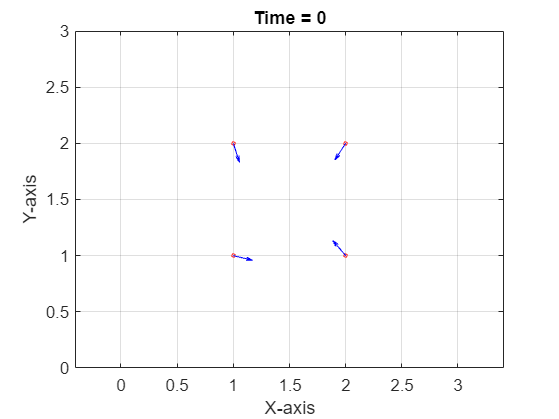

% Set the value of n and time step dt
n = 2;
dt = 0.05;

% Generate grid of points
[x, y] = meshgrid(1:n, 1:n);

% Create a matrix q to store the points and associated vectors
q = rand(n,n,2)-0.5;  % Assuming 2D vectors from a standard uniform distribution
% q0 = q;
% q1 = q0;
% q = q1;
% q = q0;
% q = q;
% q = q_bad;
% q(1,1,:) = rand(1,2)-0.5;
% q(2,2,:) = rand(1,2)-0.5;

% Normalize vectors to length 1
q_norm = sqrt(sum(q.^2, 3));  % Calculate the length of each vector
q(:,:,1) = q(:,:,1) ./ q_norm;  % Normalize x-component
q(:,:,2) = q(:,:,2) ./ q_norm;  % Normalize y-component

logs = zeros();

figure;
% Plot the current state
cla;
plot(x(:), y(:), 'ro', 'MarkerSize', 2);  % Red dots at each grid point
hold on;
quiver(x, y, q(:,:,1), q(:,:,2), 0.25, 'b');  % Blue vectors
title(['Time = ' num2str(0)]);
xlabel('X-axis');
ylabel('Y-axis');
xlim([0,n+1]);
ylim([0,n+1]);
axis equal;
grid on;
plot_name = "turning_initial1.png";
% exportgraphics(gca, plot_name);
hold off;

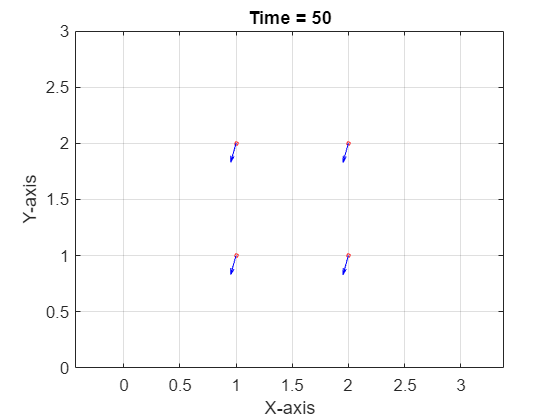


% Number of iterations
num_iterations = 1000;
H = zeros(num_iterations,1);
target = zeros(num_iterations,1);

% Main loop
for iteration = 1:num_iterations
    % Calculate turning angles for each point
    theta = get_turning(q, dt);
    theta(isnan(theta)) = 0;

    % Update vectors based on the calculated angles
    for j = 1:n
        for k = 1:n
            % Rotate the vector at point (j, k) by theta_j
            rotation_matrix = [cos(theta(j, k)), -sin(theta(j, k)); sin(theta(j, k)), cos(theta(j, k))];
            q(j, k, :) = (rotation_matrix * [q(j, k, 1); q(j, k , 2)])';
        end
    end

    idx = isnan(q);
    q(idx) = 0;
    theta_bar = 1/(n*n) * sum(sum(q));
    theta_bar = theta_bar / sqrt(sum(theta_bar.^2, 3));
    delta_theta = q - theta_bar;
    delta_theta(idx) = 0;
    delta_theta_norm = sqrt(sum(delta_theta.^2, 3));
    H(iteration) = 1/2 * sum(sum(delta_theta_norm));
    x_target = sum(q(:,:,1),"all");
    y_target = sum(q(:,:,2),"all");
    target(iteration) = atan2(y_target, x_target);
    % Pause to visualize each iteration
    % pause(0.1);
end

figure;
% Plot the current state
cla;
plot(x(:), y(:), 'ro', 'MarkerSize', 2);  % Red dots at each grid point
hold on;
quiver(x, y, q(:,:,1), q(:,:,2), 0.25, 'b');  % Blue vectors
title(['Time = ' num2str(num_iterations*dt)]);
xlabel('X-axis');
ylabel('Y-axis');
xlim([0,n+1]);
ylim([0,n+1]);
axis equal;
grid on;
plot_name = "linear_fail_state.png";
% exportgraphics(gca, plot_name);
hold off;

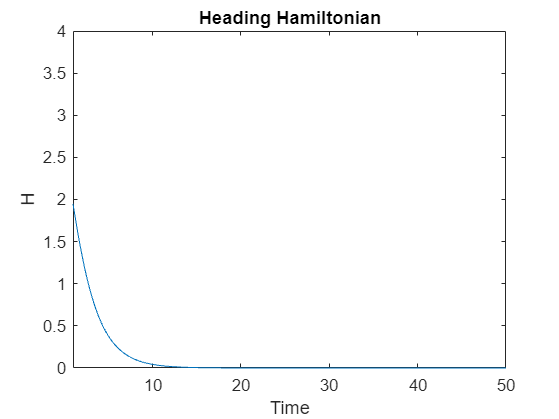


figure;

plot(linspace(1,num_iterations*dt,num_iterations)', H);
xlim([1,num_iterations*dt]);
ylim([0,n*n]);
title("Heading Hamiltonian");
xlabel("Time");
ylabel("H");

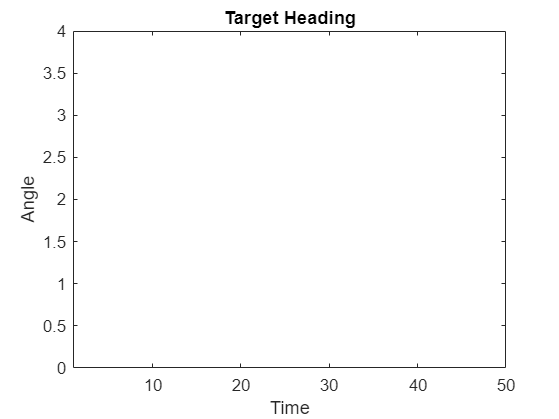

plot_name = "turning_energy1.png";
% exportgraphics(gca, plot_name);

plot(linspace(1,num_iterations*dt,num_iterations)', target);
xlim([1,num_iterations*dt]);
ylim([0,n*n]);
title("Target Heading");
xlabel("Time");
ylabel("Angle");

plot_name = "turning_energy1.png";

H_dot = zeros(size(H,1)-1,1);
for i = 1:size(H_dot,1)
    H_dot(i) = (H(i+1) - H(i)) / dt;
end
max(H_dot)

ans = -4.7167e-10

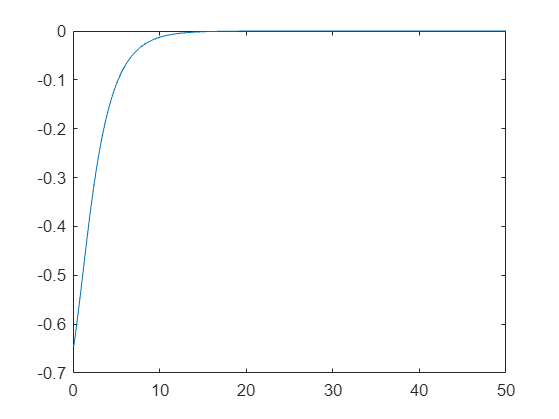

plot(linspace(0, num_iterations*dt, num_iterations-1)', H_dot);


figure;
% Plot the current state
cla;
plot(x(:), y(:), 'ro', 'MarkerSize', 2);  % Red dots at each grid point
hold on;
quiver(x, y, q(:,:,1), q(:,:,2), 0.25, 'b');  % Blue vectors
title(['Time = ' num2str(num_iterations*dt)]);
xlabel('X-axis');
ylabel('Y-axis');
xlim([0,n+1]);
ylim([0,n+1]);
axis equal;
grid on;
plot_name = "linear_fail_state.png";
exportgraphics(gca, plot_name);
hold off;

function theta = get_turning(q, dt)
    % Input:
    %   q: Matrix of headings (vectors) where each row represents a heading
    %   dt: Time step
    
    % Output:
    %   theta: Vector of angles by which each heading must be rotated

    % Get the number of headings
    num_headings = size(q, 1);

    % Initialize theta vector
    theta = zeros(num_headings);

    % Loop over each heading
    for j = 1:num_headings
        for k = 1:num_headings
            sum_term = 0;
            sum_vector = zeros(1,1,2);
            neighbour_sum = 0;
            for l = 1:num_headings
                for m = 1:num_headings
                    if ~(j == l && k == m)  % Exclude the current agent (j,k)
                        % Compute delta and eta
                        % cross = q(j,k,2)*q(l,m,1) - q(j,k,1)*q(l,m,2);
                        % dot = q(j,k,1)*q(l,m,1) + q(j,k,2)*q(l,m,2);
                        % eta_jklm = atan2(cross, dot);
                        % delta = q(j,k,:) - q(l,m,:);
                        % eta_jklm = atan2(delta(2) * q(j,k,1) - delta(1) * q(j,k,2), sum(delta .* q(j,k,:)));
                        % if eta_jklm == 0 && sum(delta .* q(j,k,:)) < 0
                        %     eta_jklm = pi;
                        % end
                        % if isnan(eta_jklm)
                        %     eta_jklm = 0;
                        % end
                        % j;
                        % k;
                        % l;
                        % m;
                        % eta_jklm/pi;
                        % Accumulate the sum term
                        % w = neighbour_weight([j,k],[l,m],0.2,1.4);
                        sum_vector = sum_vector + 1 * q(l,m,:);
                        % sum_vector = sum_vector + w * q(l,m,:);
                        % sum_term = sum_term + neighbour_weight([j,k],[l,m],0.2,1.42) * eta_jklm;
                        % sum_term = sum_term + neighbour_weight([j,k],[l,m],0.2,1.42)*sin(eta_jklm/2);
                        % neighbour_sum = neighbour_sum + neighbour_weight([j,k],[l,m],0.5,2);
                    end
                end
            end
            % sum_term = sum_term / neighbour_sum;
            % sum_term = sum_term / (num_headings^2);
            % if sum_term > 1
            %     disp(sum_term);
            % end

            % Angle between summ_vector and heading
            sum_term = atan2(sum_vector(:,:,1)*q(j,k,2)-sum_vector(:,:,2)*q(j,k,1), sum_vector(:,:,1)*q(j,k,1)+sum_vector(:,:,2)*q(j,k,2));

            % Compute angular velocity omega_j for the current heading (j)
            B = 1/pi;
            % omega_jk = tanh(B * sum_term);
            omega_jk = B * sum_term;
    
            % Compute theta_j as omega_j * dt
            theta(j,k) = -omega_jk * dt;

        end
    end
end

function out = neighbour_weight(pos1, pos2, h, r)
    d = vecnorm(pos1-pos2, 2, 2);
    if d/r >= 1
        out = 0;
    elseif d/r <= h
        out = 1;
    else
        out = (1/2) * (1 + cos(pi * ((d/r - h)/(1 - h))));
    end
end
